# GX Dataset - Comparing F30 and M30 Stimulation

## Overview

The goal of this analysis is to examine and compare behavioral and physiological outcomes from Experiment 2 of the GX dataset. 

The GX dataset explored the use of various tES types on enhancing vigilance and attention. 

The dataset included behavioral and neurophysiological outcomes quantifying stimulation related changes. 

In these analyses we focus on outcomes from: 

- Karolinska Sleepiness Scale (KSS) 

- Compensatory Tracking Task (CTT deviation) 

- Electrocardiographic monitoring (ECG - RMSSD and LF/HF ratio) 

- Electroencephalographic (EEG – PSD Frequency bandpower ratios) 

Author: Nigel Gebodh 

Last updated: April 18th 2024

Email: nigel.gebodh@gmail.com

## Background Info

### What is the GX dataset?

A dataset combining high-density electroencephalography (EEG) with physiological and continuous behavioral metrics during transcranial electrical stimulation (tES; including tDCS and tACS). Data includes within participant application of nine High-Definition tES (HD-tES) types targeted three brain regions (frontal, motor, parietal) with three waveforms (DC, 5Hz, 30Hz), with more than 783 total stimulation trials over 62 sessions with EEG, physiological (ECG or EKG, EOG), and continuous behavioral vigilance/alertness metrics.

The dataset data descriptor can be found here:

- Gebodh, N., Esmaeilpour, Z., Datta, A. et al. Dataset of concurrent EEG, ECG, and behavior with multiple doses of transcranial electrical stimulation. Nature Sci Data 8, 274 (2021).    [https://doi.org/10.1038/s41597-021-01046-y](https://doi.org/10.1038/s41597-021-01046-y)

### Where can I find the GX dataset and Code?

You can access the GX dataset in multiple formats. 

- Raw [EEG, ECG, EOG data](https://zenodo.org/record/4456079#.YOYCLuhKguW) in `.cnt` formant

- Raw [EEG, ECG, EOG data](https://openneuro.org/datasets/ds003670/versions/1.1.0) formated to comply with [BIDS](https://bids.neuroimaging.io/) standard where data are in `.set` format ([EEGlab](https://sccn.ucsd.edu/eeglab/index.php))

- Raw downsampled EEG, ECG, EOG data (1k Hz) in `.mat` format for [Experiment 1](https://zenodo.org/record/3840615#.YOYKfehKguU) and [Experiment 2](https://zenodo.org/record/3840617#.YOYKj-hKguU) (works with [MATLAB](https://www.mathworks.com/help/matlab/ref/load.html) and [Python](https://scipy-cookbook.readthedocs.io/items/Reading_mat_files.html))

- Raw behavioral [CTT data](https://zenodo.org/record/4456079#.YOYCLuhKguW) `.csv` format

- [Questionnaire data](https://zenodo.org/record/4456079/files/GX_Subject%20Info%20%26%20Behavioral%20Data.xlsx?download=1) in `.xlsx` format

The main code repository contains processing scripts and examples of how to use the GX dataset:

- [https://github.com/ngebodh/GX_tES_EEG_Physio_Behavior](https://github.com/ngebodh/GX_tES_EEG_Physio_Behavior) 

### Data Used Here

The data used here were extracted from Experiment 2 of the GX dataset.

EEG and ECG data were minimally preprocessed and measures extracted using the [YASA](https://raphaelvallat.com/yasa/build/html/index.html) and [Systole](https://embodied-computation-group.github.io/systole/#)  libraries in Python. 

For the EEG we extract PSD bandpower ratios and for the ECG we extract time (RMSSD) and frequency (LF/HF ratio) heart rate variability metrics.

The following data files are used within this code:

- `GX_KKS_Exp2.xlsx` - This contains the KSS data for F30 and M30, pre and post intervention

- `HRV_Perf_mean.csv` - This contains the CTT deviation from during to pre stimulation 

- `HRV_RMSSD.csv` - This contains the RMSSD data from during to pre stimulation

- `HRV_lf_hf_ratio.csv` - This contains the LF/HF ratio data from during to pre stimulation

- `EEG_stats_Allfeats.csv` - This contains channel-wise EEG data for PSD band power changes as well as CTT deviation data (Post-Pre)

**Note**: 

- The data from the HRV analysis only computes DURING - PRE Stimulation 

- The data from the EEG analysis only computes POST - PRE Stimulation. 

- The CTT measure that comes from the HRV is DURING-PRE 

- The CTT measure that comes from the EEG is POST- PRE 

### Required Files

To run this file you will need the following helper files:

- helper_importfile_GX_KSS_Exp2.p - imports KSS scores

- helper_GX_PlottingOutcomes_Fig_Stats.p - runs the stats and plots figures

- fdr_bh.m - computes the BH correction to the p-values. Can be downloaded [here](https://www.mathworks.com/matlabcentral/fileexchange/27418-fdr_bh).

## General Set-up

### Clear residuals

%Set code parameters
SveAllpics=1; %Save figures 0-No, 1-Yes
closefigs =0; %Close figures after saving 0-No, 1-Yes
export_date = '04182024';%Folder name with date code was run
pathsave = 'Results\'; %Folder to hold plots and stats outputs
sub_folder_name = ['FigOutput_' export_date];
warning ('off','all');

### Folder Set-up

%Create folders for results and figures    
prefix = strcat(pathsave);

    if SveAllpics==1 %1-Save output pics, 0-Don'd save output pics
        
        existance=exist(strcat(pathsave,sub_folder_name));
        if existance==0
            [s,m,mm]=mkdir(pathsave,sub_folder_name);
            prefix = strcat(pathsave,sub_folder_name,'\');
        else
        %Delete existing files
        dat_type_delete = {'fig', 'png', 'pdf', 'eps','txt'};
        for item_in =1:numel(dat_type_delete) 
            delete([pathsave sub_folder_name '\*.' dat_type_delete{item_in}]);
        end 
            prefix = strcat(pathsave,sub_folder_name,'\');
        end
    end

### Set Up Stats Holder

%Collect all stats outcomes
all_p_values={};
Table_p_val={};
stats_results ={};

## Statistics

All data were tested for adherence to normality with the Anderson-Darling’s test ( `adtest `function).  

A two-tailed paired t-test ( `ttest` function) or Wilcoxon signed rank test ( `signrank` function) was conducted under the null hypothesis that the difference between groups came from a normal distribution with unknown variances at a significance level or 5%. Data were gated between non/parametric tests based on the Anderson-Darling’s test.  

Corrections for multiple comparisons were performed using the Benjamini & Hochberg procedure ( `fdr_bh` function).

Effect sizes were calculated using Robust Cohen’s *d *( `meanEffectSize` function with *Effect = ‘robustcohen’*) or matched-pairs rank biserial correlation coefficient for the Wilcoxon signed-rank test, *r*.   

## Looking at the KSS data

Here we import the KSS outcomes. Once imported we look at the changes from pre to post for both F30 and M30 and compare arms. 

We use the Wilcoxon signed rank test for between group comparisons. 

ans = 30×8 table
     Sub      AgeYears    GenderMF        Heightcm        Weightkg    KSSPre    KSSPost    Arm
    ______    ________    ________    ________________    ________    ______    _______    ___

    {'11'}       21          F                  167.64     61.235       3          8       F30
    {'11'}       21          F                  167.64     61.235       4          4       M30
    {'12'}       20          F                  157.48     68.946       1          2       M30
    {'12'}       20          F                  157.48     68.946       3          3       F30
    {'13'}       28          F                  162.56       56.7       3          8       F30
    {'13'}       28          F               



F30 Median = 2 ± 2.875 
M30 Median = 2 ± 3.25 
z = -0.355, p = 0.72234 n=(F30:9,M30:9)
MPRB Cor Coef r = 0.156±0.333
There was no significant difference (at an alpha =0.05)in the change in KSS (Po-Pr) ratings betweenF30 (Median:2,IQR:2.875) and M30 (Median:2,IQR:3.25);
The effect size measured by MPRB Cor Coef r = 0.156 ± 0.333, indicating a small effect size




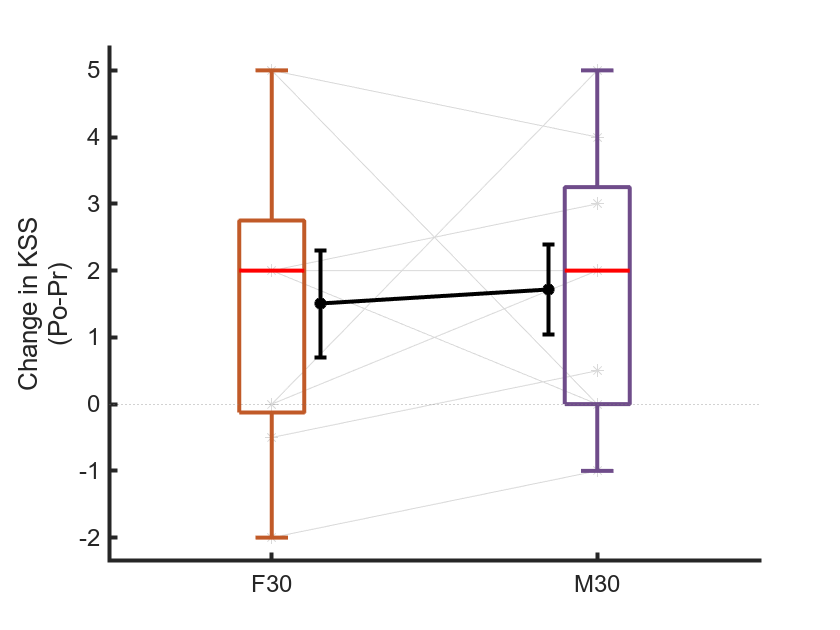

%Import the KSS values
GXKKSExp2 = helper_GX_ImportKSS_Exp2('GX_KKS_Exp2.xlsx', "Sheet1", [2, 16]);

for ii=1 %Added to keep code block together 
    t1=[];
    t1 = stack(GXKKSExp2, {["KSSpre1" "KSSpre2"] ...
                           ["KSSpost1" "KSSpost2"]...       
                           ["Arm1" "Arm2"]},...
                    "NewDataVariableName",...
                           ["KSSPre" "KSSPost" "Arm"],...
                    "IndexVariableName","Treatment");

    t1(:,{'Sub','AgeYears','GenderMF',...
          'Heightcm','Weightkg',...
          'KSSPre','KSSPost','Arm'})   


    t1_F30=t1( t1.Arm=='F30',:) ;
    ii = (t1_F30.KSSPost - t1_F30.KSSPre);
    
    [~,~,idx] = unique(t1_F30.StartingID,'stable');  
    t1_F30_merged=accumarray(idx,ii,[],@median) ;
     
    t1_M30=t1( t1.Arm=='M30',:) ;
    ii = (t1_M30.KSSPost - t1_M30.KSSPre);
    
    [~,~,idx] = unique(t1_M30.StartingID,'stable');  
    t1_M30_merged=accumarray(idx,ii,[],@median); 
    y_var='KSS';
    var_in= y_var; 
    diff_period ='Po-Pr';  
    
    figure;
    [stats_out,p] = helper_GX_PlottingOutcomes_Fig_Stats(var_in,...
                    t1_F30_merged,t1_M30_merged, diff_period);   

    fprintf ('\n%s\n',stats_out)    
    stats_results{end+1}=stats_out;
    Table_p_val{end+1,1}=var_in;
    Table_p_val{end,2}=p;
    
    
    fname=[strcat('GX_F30vM30_Behavior_', var_in)];
    
     if SveAllpics==1
           h = gcf;
           saveas(h,strcat(prefix,fname,'.fig'),'fig');
           print(h,'-dpng', strcat(prefix,fname,'.png'), '-r600');
           print(h,'-dpdf', [prefix,fname], '-r600');
    
     end
     if closefigs==1, close all,  end


end 

## Cardiac HRV Outcomes

Here we look at the cardiac outcomes for time (RMSSD) and frequency (LF/HF ratio). 

Running:Perf_mean


t1 = 18×5 table
    Var1         Perf_mean         Participant    StimType         Period      
    ____    ___________________    ___________    ________    _________________

     0      -0.0169085146516345          11       {'F30'}     {'PercentChange'}
     1      0.00250865885511073          13       {'F30'}     {'PercentChange'}
     2       0.0661535614054519          14       {'F30'}     {'PercentChange'}
     3      0.00898682293133632          16       {'F30'}     {'PercentChange'}
     4      -0.0545129645289705          20       {'F30'}     {'PercentChange'}
     5       -0.226493437814626        1219       {'F30'}     {'PercentChange'}
     6       0.0562153597794672        1518       {'F30'}     {'PercentChange'}
     7       -0.426592834784715      212526       {'F30'}     {'PercentChange'}
     8       



F30 Mean = -9.60877 ± 17.1836 
M30 Mean = -6.00818 ± 17.7388 
t(8) = -6.4991, p = 0.00018828 n=(F30:9,M30:9)
Cohen's d = -0.163(-0.801,-0.079)
There was a significant difference (at an alpha =0.05)in the change in Perf mean(D-Pr) (During minus Pre) ratings betweenF30 (Mean:-9.609±17.184) and M30 (Mean:-6.008±17.739);
The effect size measured by Cohen's d = -0.163 ± 0.084, indicating a small effect size




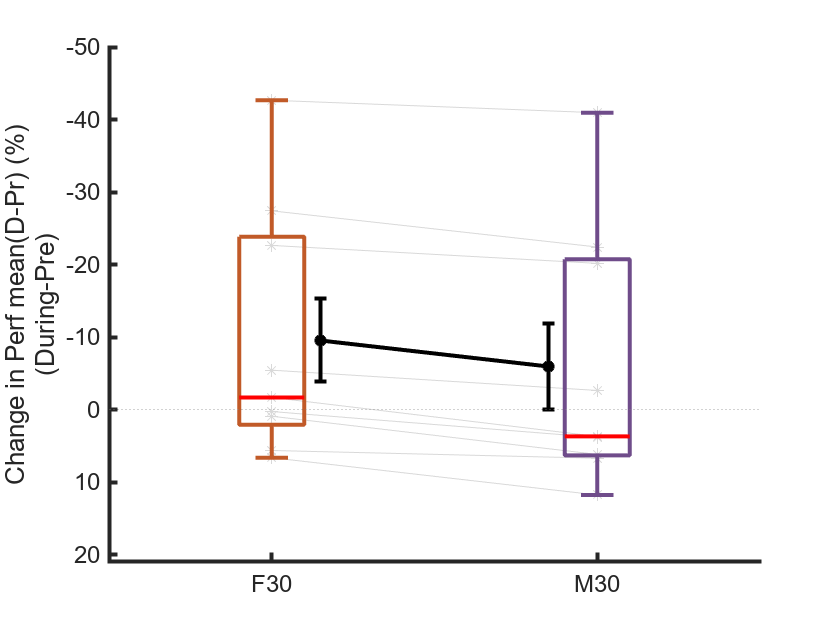

Running:RMSSD


t1 = 18×5 table
    Var1           RMSSD           Participant    StimType         Period      
    ____    ___________________    ___________    ________    _________________

     0       0.0968231163464185          11       {'F30'}     {'PercentChange'}
     1         0.53679218233035          13       {'F30'}     {'PercentChange'}
     2         1.70098205900038          14       {'F30'}     {'PercentChange'}
     3      -0.0249375074746126          16       {'F30'}     {'PercentChange'}
     4       0.0464883152649849          20       {'F30'}     {'PercentChange'}
     5        0.119107676142218        1219       {'F30'}     {'PercentChange'}
     6        0.328962130952455        1518       {'F30'}     {'PercentChange'}
     7       0.0689944600196368      212526       {'F30'}     {'PercentChange'}
     8       



F30 Median = 9.68231 ± 33.8352 
M30 Median = 3.61183 ± 56.785 
z = 0.178, p = 0.85895 n=(F30:9,M30:9)
MPRB Cor Coef r = 0.067±0.4
There was no significant difference (at an alpha =0.05)in the change in RMSSD(D-Pr) (During minus Pre) ratings betweenF30 (Median:9.682,IQR:33.835) and M30 (Median:3.612,IQR:56.785);
The effect size measured by MPRB Cor Coef r = 0.067 ± 0.4, indicating a small effect size




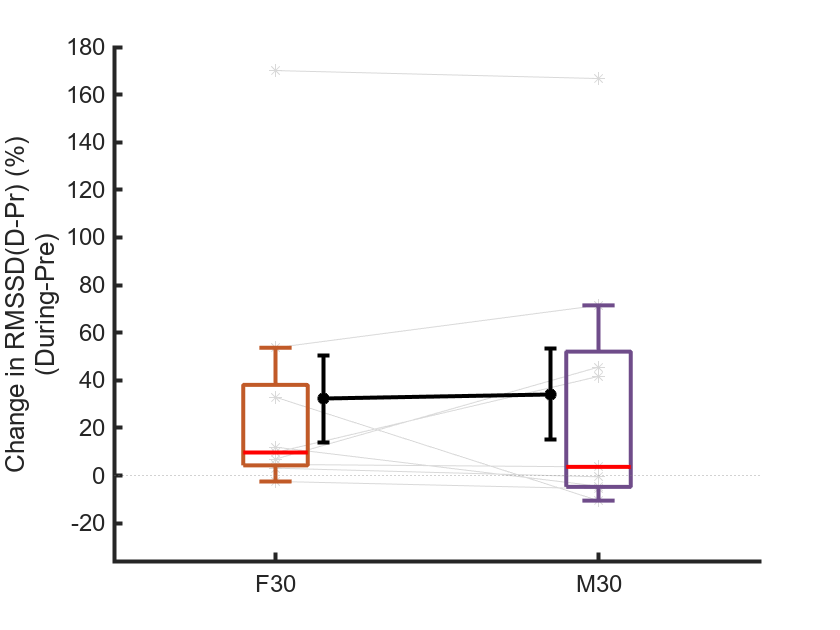

Running:lf_hf_ratio


t1 = 18×5 table
    Var1       lf_hf_ratio       Participant    StimType         Period      
    ____    _________________    ___________    ________    _________________

     0       1.34527690825525          11       {'F30'}     {'PercentChange'}
     1       2.43943159013945          13       {'F30'}     {'PercentChange'}
     2       1.63532790312737          14       {'F30'}     {'PercentChange'}
     3       2.44654830252285          16       {'F30'}     {'PercentChange'}
     4       8.27503645458336          20       {'F30'}     {'PercentChange'}
     5      0.836832306719736        1219       {'F30'}     {'PercentChange'}
     6       3.46218431503114        1518       {'F30'}     {'PercentChange'}
     7        2.5814325050694      212526       {'F30'}     {'PercentChange'}
     8       1.48887198640673    



F30 Median = 243.943 ± 134.865 
M30 Median = 99.1098 ± 138.322 
z = 1.599, p = 0.10974 n=(F30:9,M30:9)
MPRB Cor Coef r = 0.6±0.267
There was no significant difference (at an alpha =0.05)in the change in lf hf ratio(D-Pr) (During minus Pre) ratings betweenF30 (Median:243.943,IQR:134.865) and M30 (Median:99.11,IQR:138.322);
The effect size measured by MPRB Cor Coef r = 0.6 ± 0.267, indicating a large effect size




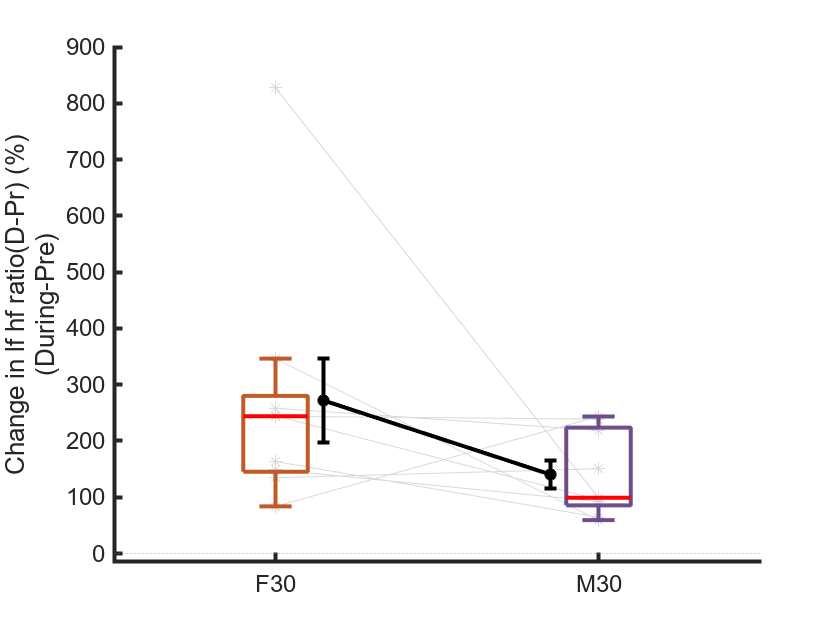

files_in_folder=ls('*.csv');
diff_period ='During minus Pre';

HRV_stats_results={}; 
for file_num=1:size(files_in_folder,1)

file_in = files_in_folder(file_num,:);
if ~contains(file_in,'HRV_All_') && ~contains(file_in,'EEG')
    
    file_in = strrep(file_in,' ','');
    var_in=string(file_in(5:end-4));

    disp(strcat('Running: ', var_in));


    T= readtable([file_in]);
    t1=T


    t1_F30=t1( t1.StimType=="F30" &  t1.Participant>10,:) ;
    t1_F30_merged=t1_F30.(var_in).*100 ;

    t1_M30=t1( t1.StimType=="M30" &  t1.Participant>10,:);
    t1_M30_merged=t1_M30.(var_in).*100; 
    
    var_in= strrep(var_in,'_',' ');
    var_in=char(var_in);
  

    var_in = [var_in,'(D-Pr)'];


    figure;
    [stats_out,p] = helper_GX_PlottingOutcomes_Fig_Stats(var_in,...
                        t1_F30_merged,t1_M30_merged, diff_period); 

    fprintf ('\n%s\n',stats_out);    
    stats_results{end+1}=stats_out;
    Table_p_val{end+1,1}=var_in;
    Table_p_val{end,2}=p;


    fname=char([strcat('GX_F30vM30_HRV_', var_in)]);

    if SveAllpics==1
           h = gcf;
           saveas(h,strcat(prefix,fname,'.fig'),'fig');
           saveas(h,strcat(prefix,fname,'.png'),'png');
           print(h,'-dpng', strcat(prefix,fname,'.png'), '-r600');
           print(h,'-depsc', strcat(prefix,fname,'.eps'), '-r600');
           print(h,'-dpdf', [prefix,fname], '-r600');
       end
     if closefigs==1, close all,  end      



end 
end

## EEG Outcomes 

Here we look at the EEG outcomes. We also look at the CTT deviation ('Perf_mean') for post-pre. 

Running:Perf_mean


ans = 9×5 table
    Participant       CTT        StimType         Period            Feature  
    ___________    __________    ________    _________________    ___________

          11       -4.7347786    {'F30'}     {'PercentChange'}    "Perf_mean"
          13       -3.9573892    {'F30'}     {'PercentChange'}    "Perf_mean"
          14       -3.5847967    {'F30'}     {'PercentChange'}    "Perf_mean"
          16       -4.1841026    {'F30'}     {'PercentChange'}    "Perf_mean"
          20        3.9765492    {'F30'}     {'PercentChange'}    "Perf_mean"
        1219       -5.6071924    {'F30'}     {'PercentChange'}    "Perf_mean"
        1518        0.5219996    {'F30'}     {'PercentChange'}    "Perf_mean"
      212526       -6.1725393    {'F30'}     {'PercentChange'}    "Perf_mean"
      222324        2.7046032    

ans = 9×5 table
    Participant       CTT        StimType         Period            Feature  
    ___________    __________    ________    _________________    ___________

          11        0.3412398    {'M30'}     {'PercentChange'}    "Perf_mean"
          13        9.0218821    {'M30'}     {'PercentChange'}    "Perf_mean"
          14        1.0662477    {'M30'}     {'PercentChange'}    "Perf_mean"
          16       -3.0597716    {'M30'}     {'PercentChange'}    "Perf_mean"
          20         4.920055    {'M30'}     {'PercentChange'}    "Perf_mean"
        1219        2.7655294    {'M30'}     {'PercentChange'}    "Perf_mean"
        1518        2.9239482    {'M30'}     {'PercentChange'}    "Perf_mean"
      212526        3.2471711    {'M30'}     {'PercentChange'}    "Perf_mean"
      222324        1.7645155    



F30 Mean = -2.33752 ± 3.74503 
M30 Mean = 2.55454 ± 3.30419 
t(8) = -3.2015, p = 0.012583 n=(F30:9,M30:9)
Cohen's d = -1.212(-3.669,-0.439)
There was a significant difference (at an alpha =0.05)in the change in Perf mean(Po-Pr) (Post minus Pre) ratings betweenF30 (Mean:-2.338±3.745) and M30 (Mean:2.555±3.304);
The effect size measured by Cohen's d = -1.212 ± 0.773, indicating a large effect size




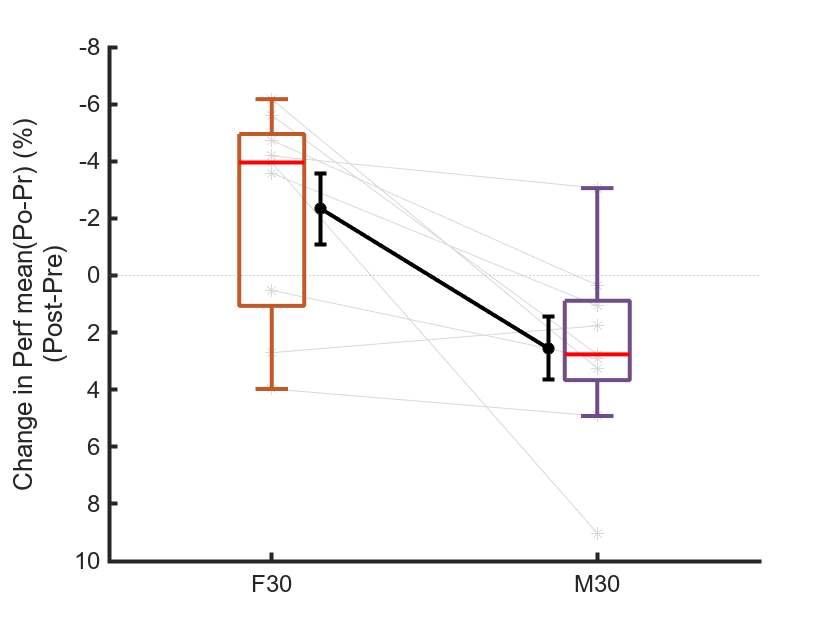

Running:at


ans = 9×36 table
        Fp1             Fpz             Fp2              F7              F3              Fz              F4              F8             FC5             FC1             FC2             FC6              M1              T7              C3              Cz              C4              T8              M2             CP5             CP1             CP2             CP6              P7              P3              Pz              P4              P8             POz              O1

ans = 9×36 table
        Fp1             Fpz             Fp2              F7              F3              Fz              F4              F8             FC5             FC1             FC2             FC6              M1              T7              C3              Cz              C4              T8              M2             CP5             CP1             CP2             CP6              P7              P3              Pz              P4              P8             POz              O1



F30 Median = 0.604077 ± 19.5926 
M30 Median = 0.654815 ± 7.85086 
z = 1.125, p = 0.26039 n=(F30:9,M30:9)
MPRB Cor Coef r = 0.422±0.222
There was no significant difference (at an alpha =0.05)in the change in Alpha Theta Ratio (Post minus Pre) ratings betweenF30 (Median:0.604,IQR:19.593) and M30 (Median:0.655,IQR:7.851);
The effect size measured by MPRB Cor Coef r = 0.422 ± 0.222, indicating a medium effect size




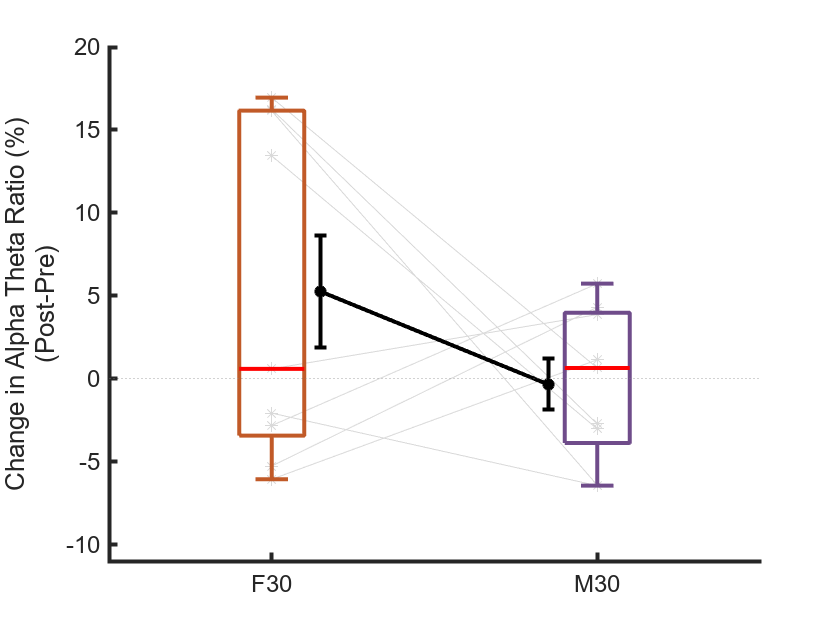

Running:dt


ans = 9×36 table
        Fp1             Fpz             Fp2              F7              F3              Fz              F4              F8             FC5             FC1             FC2             FC6              M1              T7              C3             Cz              C4              T8              M2             CP5             CP1             CP2             CP6              P7              P3              Pz              P4              P8             POz              O1

ans = 9×36 table
        Fp1             Fpz             Fp2              F7              F3              Fz              F4              F8             FC5             FC1             FC2             FC6              M1              T7              C3              Cz              C4              T8              M2             CP5             CP1             CP2             CP6              P7              P3              Pz              P4              P8             POz              O1



F30 Mean = 4.57382 ± 5.07161 
M30 Mean = 1.01349 ± 5.04552 
t(8) = 4.1947, p = 0.0030183 n=(F30:9,M30:9)
Cohen's d = 0.686(0.292,2.338)
There was a significant difference (at an alpha =0.05)in the change in Delta Theta Ratio (Post minus Pre) ratings betweenF30 (Mean:4.574±5.072) and M30 (Mean:1.013±5.046);
The effect size measured by Cohen's d = 0.686 ± -1.652, indicating a large effect size




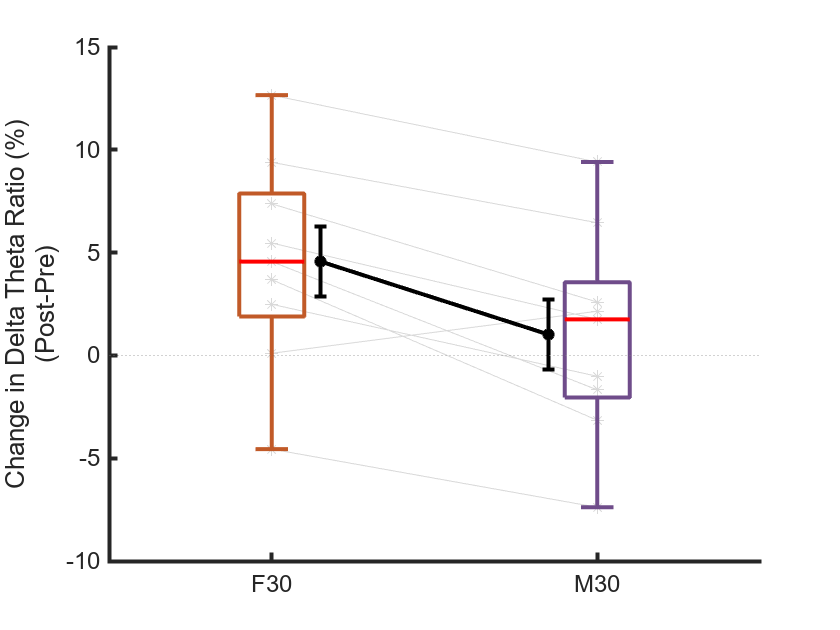

files_in_folder=ls('*.csv');
file_in= 'EEG_stats_Allfeats.csv';
diff_period ='Post minus Pre';
select_feats = ["Perf_mean", "at", "dt"];
EEG_stats_results={}; 


T= readtable([file_in]);

t1=T;
t1.Feature=string(t1.Feature);

Features = string(unique(t1.Feature));
Features = Features(contains(Features,  select_feats ));


for ii_feat=1:length(Features)
 
    var_in=Features(ii_feat);
    
    disp(strcat('Running: ', var_in));
    
    chan_mean =["P8","P4","O2","P7","P3","O1"]; 
    
    t1_F30=t1( t1.StimType=="F30" &  t1.Participant>10 &  t1.Feature==var_in,:); 
    t1_F30_merged=mean(t1_F30{:,[chan_mean]}.*100, 2);
    
    
    t1_M30=t1( t1.StimType=="M30" &  t1.Participant>10 &  t1.Feature==var_in,:);
    t1_M30_merged=mean(t1_M30{:,[chan_mean]}.*100, 2);
    
    if contains(var_in, "Perf_mean")
        t1_F30.CTT = t1_F30{:,'Fp1'}.*100;%The CTT are just repeated across channels.
        t1_M30.CTT = t1_M30{:,'Fp1'}.*100;
        t1_F30(:,{'Participant','CTT','StimType','Period','Feature'})
        t1_M30(:,{'Participant','CTT','StimType','Period','Feature'})
    else
        t1_F30(:,2:end)
        t1_M30(:,2:end)

    end 

    var_in= strrep(var_in,'_',' ');
    var_in=char(var_in);
    
    
    if var_in=="at";
        var_in="Alpha Theta Ratio";
    elseif  var_in=="dt";
        var_in="Delta Theta Ratio";
    elseif var_in=="Perf mean"
        var_in = 'Perf mean(Po-Pr)';
    end 
    
    
        
    figure;
    [stats_out,p] = helper_GX_PlottingOutcomes_Fig_Stats(var_in,...
                    t1_F30_merged,t1_M30_merged, diff_period);   
    
        
        fprintf ('\n%s\n',stats_out);
        stats_results{end+1}=stats_out;
        
        Table_p_val{end+1,1}=var_in;
        Table_p_val{end,2}=p;
        
        fname=char([strcat('GX_F30vM30_EEG_', var_in)]);
    
        
         if SveAllpics==1
               h = gcf;
               saveas(h,strcat(prefix,fname,'.fig'),'fig');
               saveas(h,strcat(prefix,fname,'.png'),'png');
               print(h,'-dpng', strcat(prefix,fname,'.png'), '-r600');
               print(h,'-depsc', strcat(prefix,fname,'.eps'), '-r600');
               print(h,'-dpdf', [prefix,fname], '-r600');
           end
         if closefigs==1, close all,  end      



end

## Organize All Statistics

Here we gather all the p-values from the statistical tests run above and perform the BH correction. 

%Get all our collected stats
All_stats_results=reshape(stats_results,size(stats_results,2),1);


TT=cell2table(Table_p_val,'Variable',{'Var','pval'})

TT = 7×2 table
            Var                    pval        
    ___________________    ____________________

    "KSS"                     0.722338991965049
    "Perf mean(D-Pr)"      0.000188282224883795
    "RMSSD(D-Pr)"             0.858954922737482
    "lf hf ratio(D-Pr)"       0.109744638747013
    "Perf mean(Po-Pr)"       0.0125831584162648
    "Alpha Theta Ratio"       0.260392943610483
    "Delta Theta Ratio"     0.00301827496326444


#### BH Correct p-values

We adjust the p-values using the Benjamini & Hochberg procedure. 

The `fdr_bh` function can be found [here](https://www.mathworks.com/matlabcentral/fileexchange/27418-fdr_bh).

%These are the variables to correct p-vals
vars_to_test= {'KSS','Perf mean(D-Pr)',...
                'Perf mean(Po-Pr)',...
                'RMSSD(D-Pr)',...
                'lf hf ratio(D-Pr)',...
                'Alpha Theta Ratio',...
                'Delta Theta Ratio'};

TT2= TT(ismember(TT.Var,vars_to_test),:);

%Note that Perf_mean is seen twice. The 1st one if Perf_mean from pre to
%during and the 2nd is Perf_mean from pre to post. 

[h, crit_p, adj_ci_cvrg, adj_p]=fdr_bh(TT2.pval,0.05,'pdep','yes');

Out of 7 tests, 3 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or positively dependent tests.


TT2.BH_adjusted_pval=adj_p;
TT2.rounded_pval=round(adj_p,3)

TT2 = 7×4 table
            Var                    pval             BH_adjusted_pval      rounded_pval
    ___________________    ____________________    ___________________    ____________

    "KSS"                     0.722338991965049      0.842728823959224       0.843    
    "Perf mean(D-Pr)"      0.000188282224883795    0.00131797557418656       0.001    
    "RMSSD(D-Pr)"             0.858954922737482      0.858954922737482       0.859    
    "lf hf ratio(D-Pr)"       0.109744638747013      0.192053117807273       0.192    
    "Perf mean(Po-Pr)"       0.0125831584162648     0.0293607029712846       0.029    
    "Alpha Theta Ratio"       0.260392943610483      0.364550121054677       0.365    
    "Delta Theta Ratio"     0.00301827496326444     0.0105639623714256       0.011    


These are the p-values for all the otucome measures. 

#### Show Significant Outcomes

Once we have the corrected values we can print our significant outcomes. 

TT3=table(TT2.Var(h), TT2.pval(h), ...
        adj_p(h),...
        'VariableNames',...
        ["VarName","OriginalP","AdjustedP"]);

TT3.RoundedAdjustedP = round(adj_p(h),3)

TT3 = 3×4 table
          VarName               OriginalP               AdjustedP         RoundedAdjustedP
    ___________________    ____________________    ___________________    ________________

    "Perf mean(D-Pr)"      0.000188282224883795    0.00131797557418656         0.001      
    "Perf mean(Po-Pr)"       0.0125831584162648     0.0293607029712846         0.029      
    "Delta Theta Ratio"     0.00301827496326444     0.0105639623714256         0.011      


#### Save Stats Outcomes

Once we have all out stats outcomes we save them to a text file for easy viewing. 

%Write results to table
fname='All_stats_results.txt';
writecell(All_stats_results,[prefix,fname])

fname='All_stats_results_p_vals.txt';
writetable(TT,[prefix,fname],'Delimiter','|')  

fname='All_stats_results_sig_corrected_p_vals.txt';
writetable(TT3,[prefix,fname],'Delimiter','|')

%Export file to HTML
export('GX_F30vM30_Analysis.mlx', format='html');